% plot variables here
titlefsz = 20;
textfsz = 17;
axfsz = 15;
linewidth = 2;

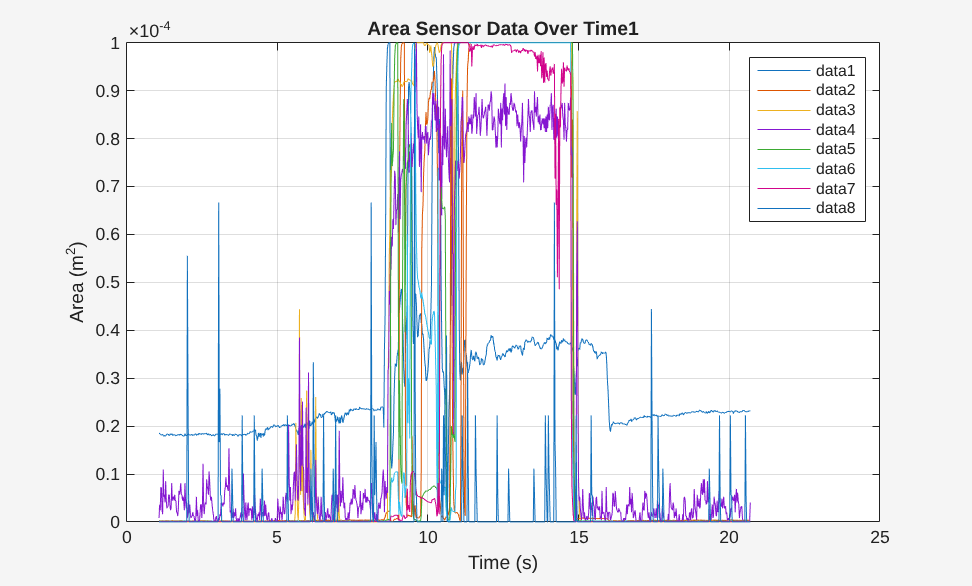

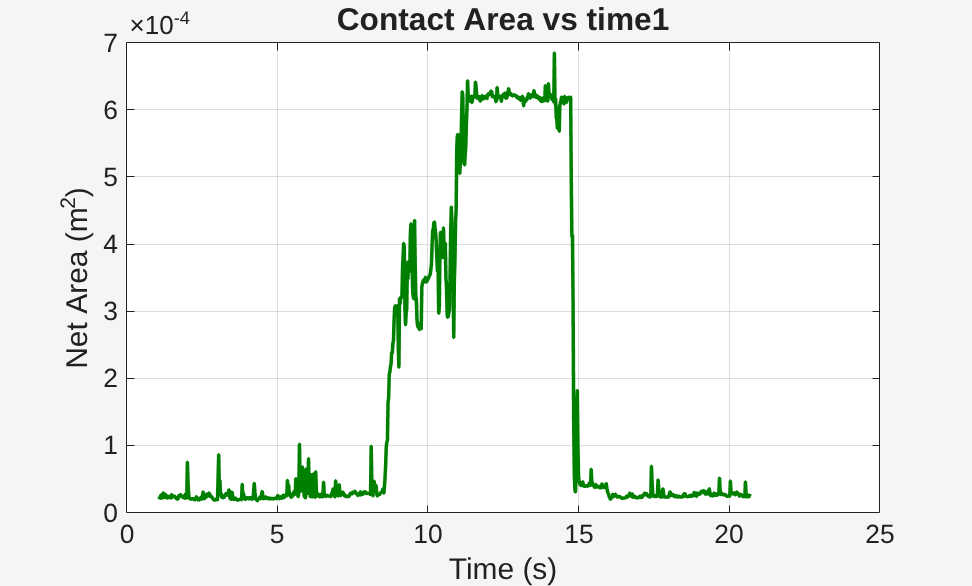

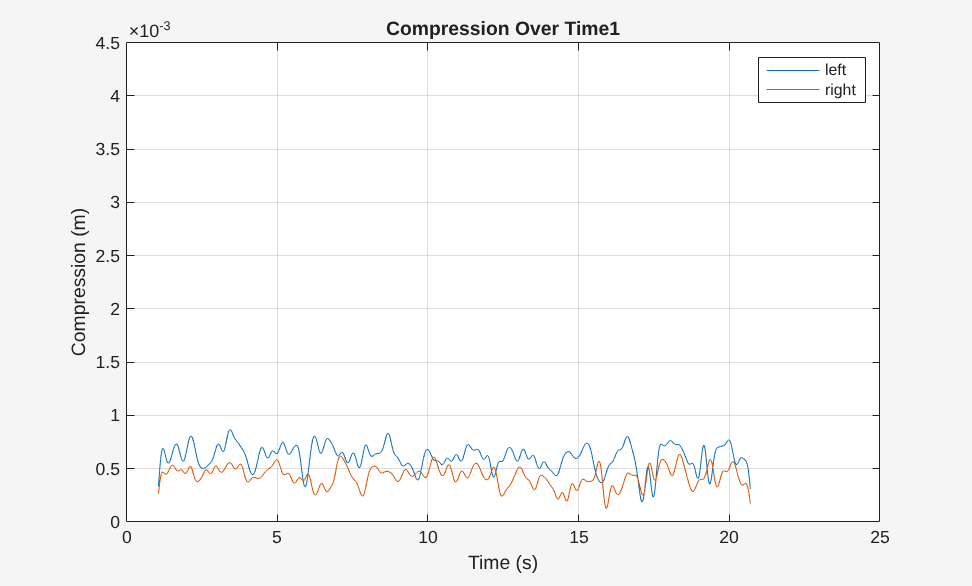

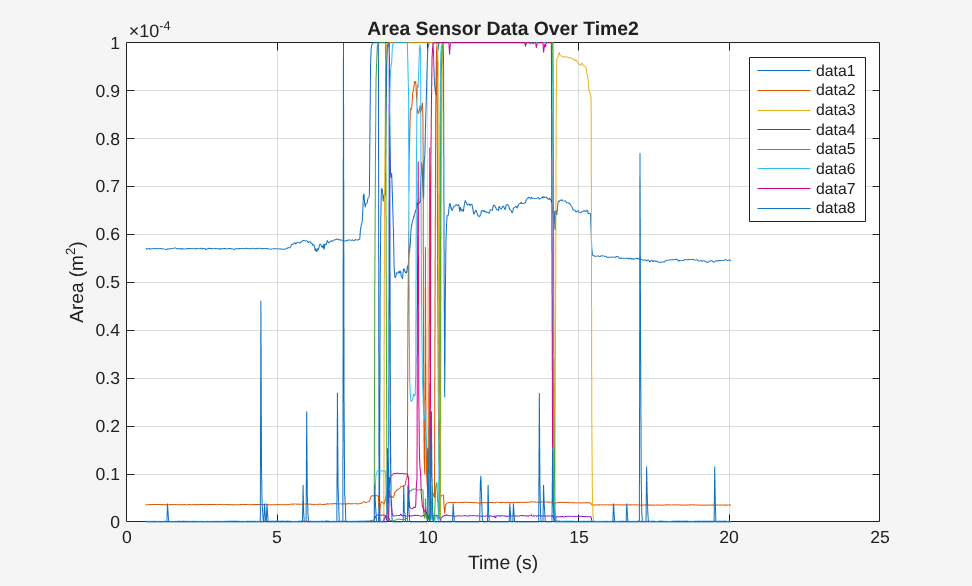

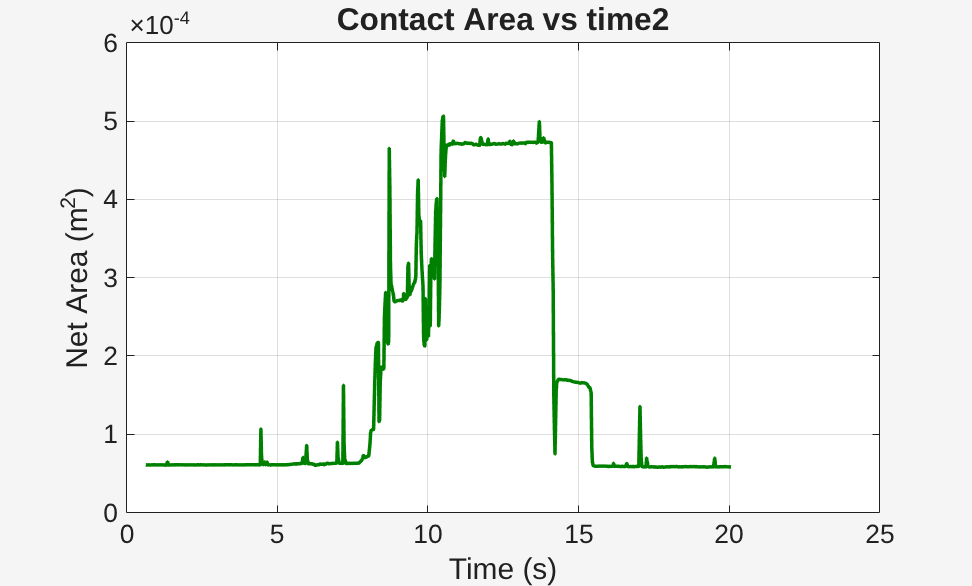

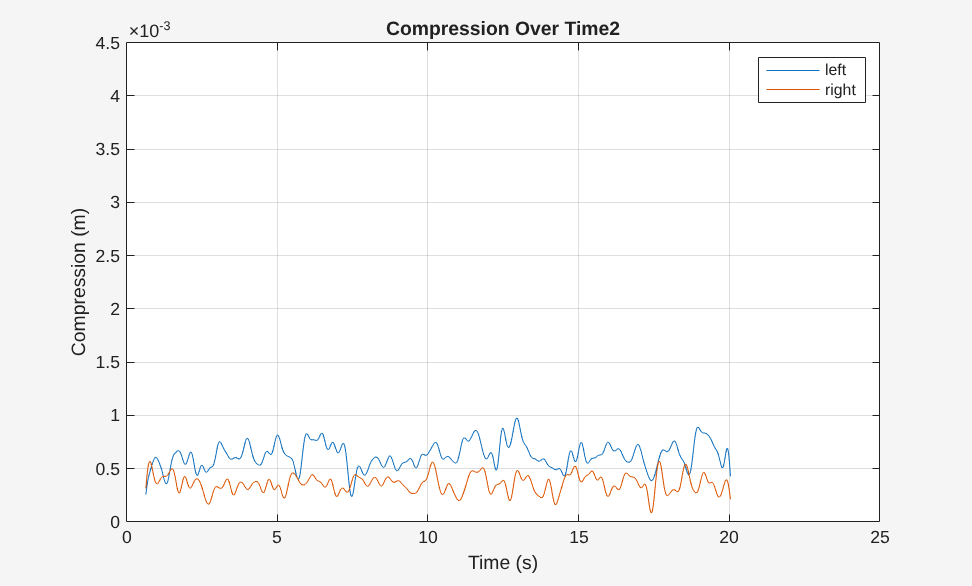

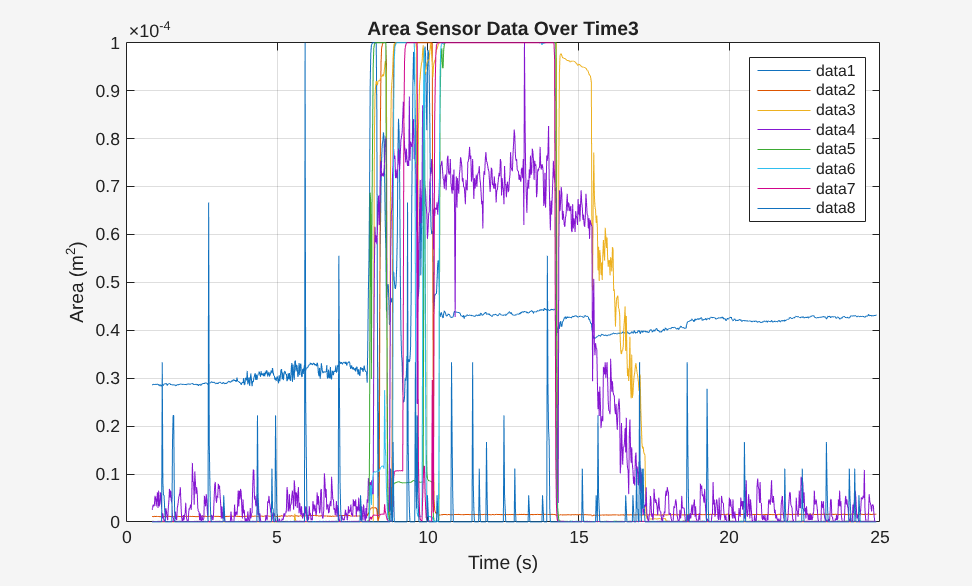

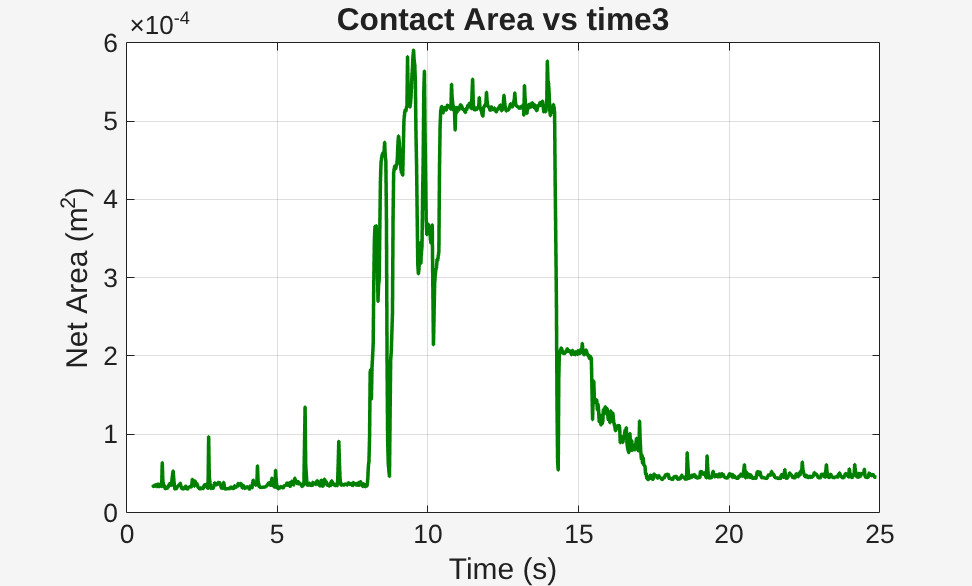

expts = ["1";"2";"3";"4";"5";"6";"7";"8";"9";"10";"11"];
expt_path_prefix = "rigid_gripper_expts_2/expt_";
% read messages from 
% /area_sensor/float_array
% /object_linear_encoder/float_array

for file_i=1:size(expts,1)
    expt_file = expt_path_prefix + expts(file_i);

    bag = ros2bagreader(expt_file);
    
    areaSensorBag = select(bag,"Topic", "/area_sensor/float_array");
    objectEncoderBag = select(bag,"Topic", "/object_linear_encoder/float_array");
    areaSensorMsgs = readMessages(areaSensorBag);
    objectEncoderMsgs = readMessages(objectEncoderBag);
    
    start_time = bag.StartTime;
    end_time = bag.EndTime;
    sample_freq = 50;
    t = (start_time:1/sample_freq:end_time)';
    t_biased = t-t(1);
    n = size(t,1);
    an = size(areaSensorMsgs,1);
    
    area = zeros(8,an,"double"); %8xn vector containing area
    at = zeros(an,1,"double"); %nx1 vector containing timestamps
    % first 4 is right finger, second 4 is left
    
    for i=1:an
        at(i) = areaSensorMsgs{i}.data(1);
        area(:,i) = areaSensorMsgs{i}.data(2:9);
    end
    
    at = at - start_time;
    % figure;
    % theme(figure,"light");
    % plot(at,area(:,:));
    % hold on;
    % legend;
    % xlabel('Time (s)');
    % ylabel('Area Measurements');
    % title('Area Sensor Data Over Time');
    % xlim([0 25]);
    % grid on;
    % hold off;
    net_area = zeros(1,an);
    for i=1:8
        area(i,:) = area(i,:) - min(area(i,:));
        area(i,:) = area(i,:)/max(area(i,:));
        area(i,:) = 1e-4*area(i,:);
        net_area = area(i,:) + net_area;
    end
    
    % individual area plots
    figure;
    theme(figure,"light");
    plot(at,area(:,:));
    hold on;
    legend;
    xlabel('Time (s)');
    ylabel('Area (m^2)');
    title('Area Sensor Data Over Time' + expts(file_i));
    xlim([0 25]);
    grid on;
    hold off;
    
    % net area plots
    figure;
    theme(figure,"light");
    plot(at,net_area',"LineWidth",linewidth,"Color",[0 0.5 0]);
    hold on;
    ax = gca;
    ax.FontSize = axfsz;
    xlabel('Time (s)','FontSize',textfsz);
    ylabel('Net Area (m^2)','FontSize',textfsz);
    title('Contact Area vs time' + expts(file_i),'FontSize',titlefsz-2);
    xlim([0 25]);
    grid on;
    hold off;
    
    net_area = net_area';
    on = size(objectEncoderMsgs,1);
    
    % first is left second is right
    objectEncoder = zeros(2,on); % 2xn array of object data
    ot = zeros(on,1); % nx1 vector containing timestamps
    
    for i=1:on
        ot(i) = objectEncoderMsgs{i}.data(1);
        objectEncoder(:,i) = objectEncoderMsgs{i}.data(2:3);
    end
    
    ot = ot -start_time;
    enc = (36*(objectEncoder'./3.3) - 30)./((objectEncoder'./3.3) -1);
    enc(:,1) = enc(:,1) - min(enc(:,1));
    enc(:,2) = enc(:,2) - min(enc(:,2));
    enc = 1e-3*enc;
    enc(:,1) = lowpass(enc(:,1),0.05);
    enc(:,2) = lowpass(enc(:,2),0.05);
    
    % individual compression plot
    figure
    theme(figure,"light");
    plot(ot,enc(:,1));
    hold on;
    plot(ot,enc(:,2));
    xlabel("Time (s)");
    ylabel("Compression (m)");
    title("Compression Over Time" + expts(file_i));
    legend(["left","right"]);
    xlim([0,25]);
    ylim([0,4.5e-3]);
    grid on;
    hold off;
    
    % net_enc = enc(:,1) + enc(:,2);
    % 
    % figure;
    % theme(figure,"light");
    % plot(ot,net_enc,"LineWidth",linewidth,"Color","red");
    % hold on;
    % ax = gca;
    % ax.FontSize = axfsz;
    % title("Net compression vs time","FontSize",titlefsz-2);
    % ylabel("Net compression(m)","FontSize",textfsz);
    % xlabel("Time (s)","FontSize",textfsz);
    % grid on;
    % saveas(gcf,"Net Compression over time full expt.png")
    % hold off;
end